Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 6 -- FFT of data

%{
    This will be a script that will solve the problems in Assignment 6 and
    assignment 6a. 

    Sam Kramer
    Feb 8th, 2023
%}

% --Script setup
    clear; clc; close all; format compact;

    There are multiple frequencies in the posted data set (assignment 6). The sample rate is 1024 samples/sec. Using the integral technique for Fourier series;

Estimate the amplitude and phase of the 15 HZ and 35 Hz signals ie write code to do this estimation, remember , Livescript.

% --Parameters
    fs = 1024;          % Sample Frequency
    magnitude = [];     % magnitude solution Vector
    phase = [];         % Phase solution vector

%%%%%%%%%%%%%%%%%%%%%%%%%%%% Initial Data Plotting %%%%%%%%%%%%%%%%%%%%%%%%%
    
% --Load in Data
    a6data = load('6data.mat');
    
    % --Reformat data
        signal = a6data.sig;    % Define the signal
        T = a6data.t;           % Define the period
        N = length(signal);     % Length of signal
        t = 1/N;                % Time step of signal
        w0 = 1:N;               % Frequency 
    
% --Plot data
    plot(T,signal);
        title('Raw Signal Data')
        xlabel('Time (s)')

The sample frequency is 1024 and the number of datapoints is 1024, so the time is 1 second 


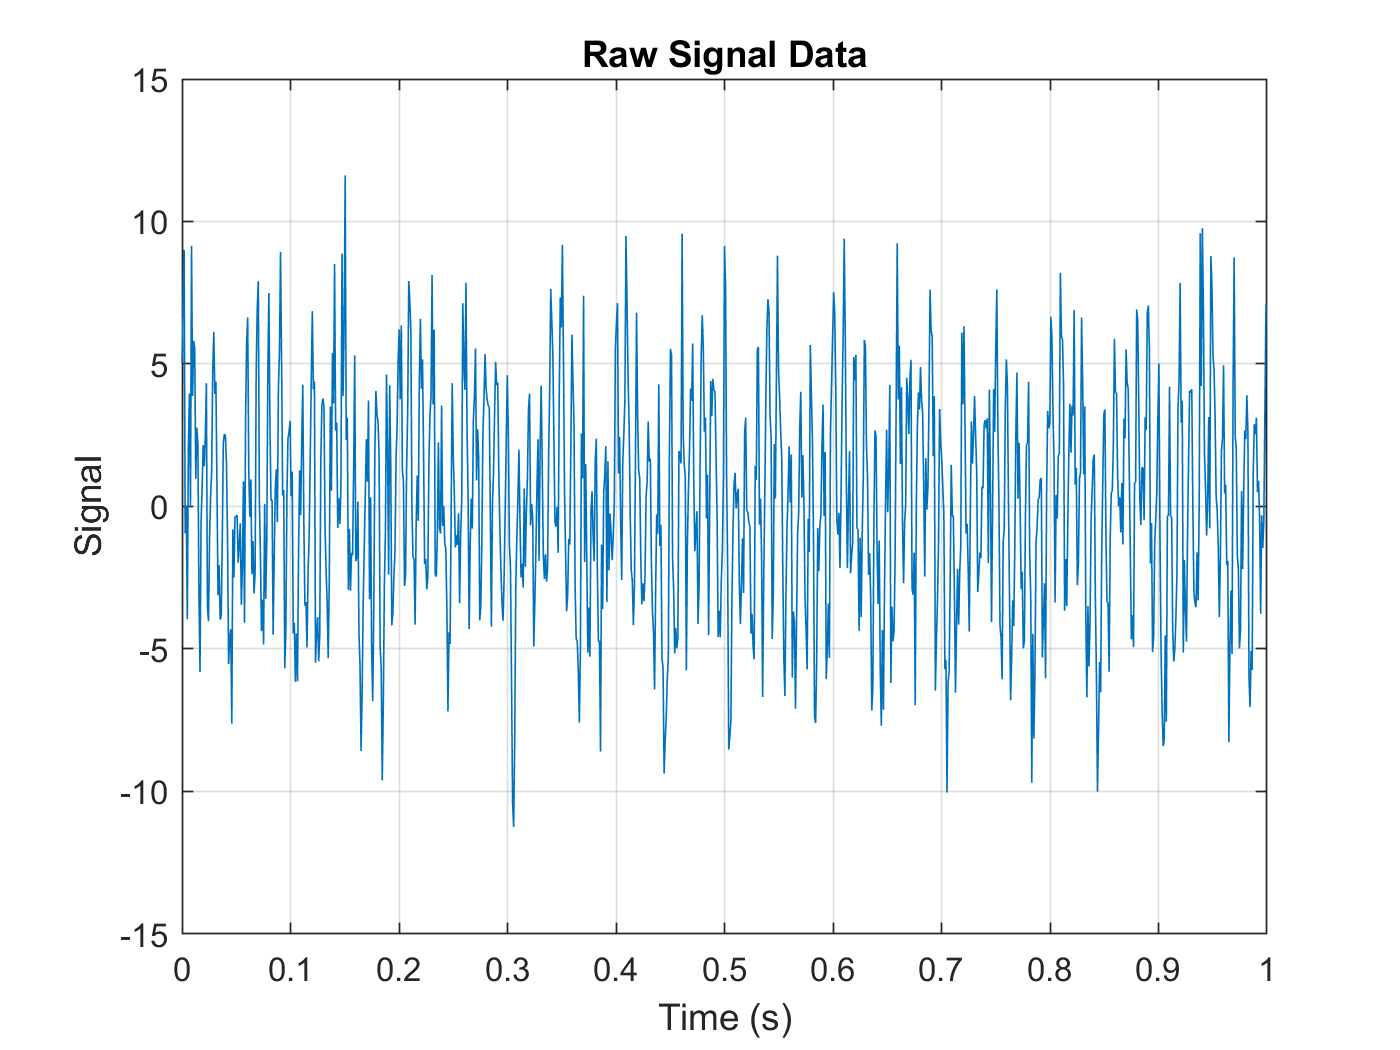

        ylabel('Signal')
        hold on;
        grid on;

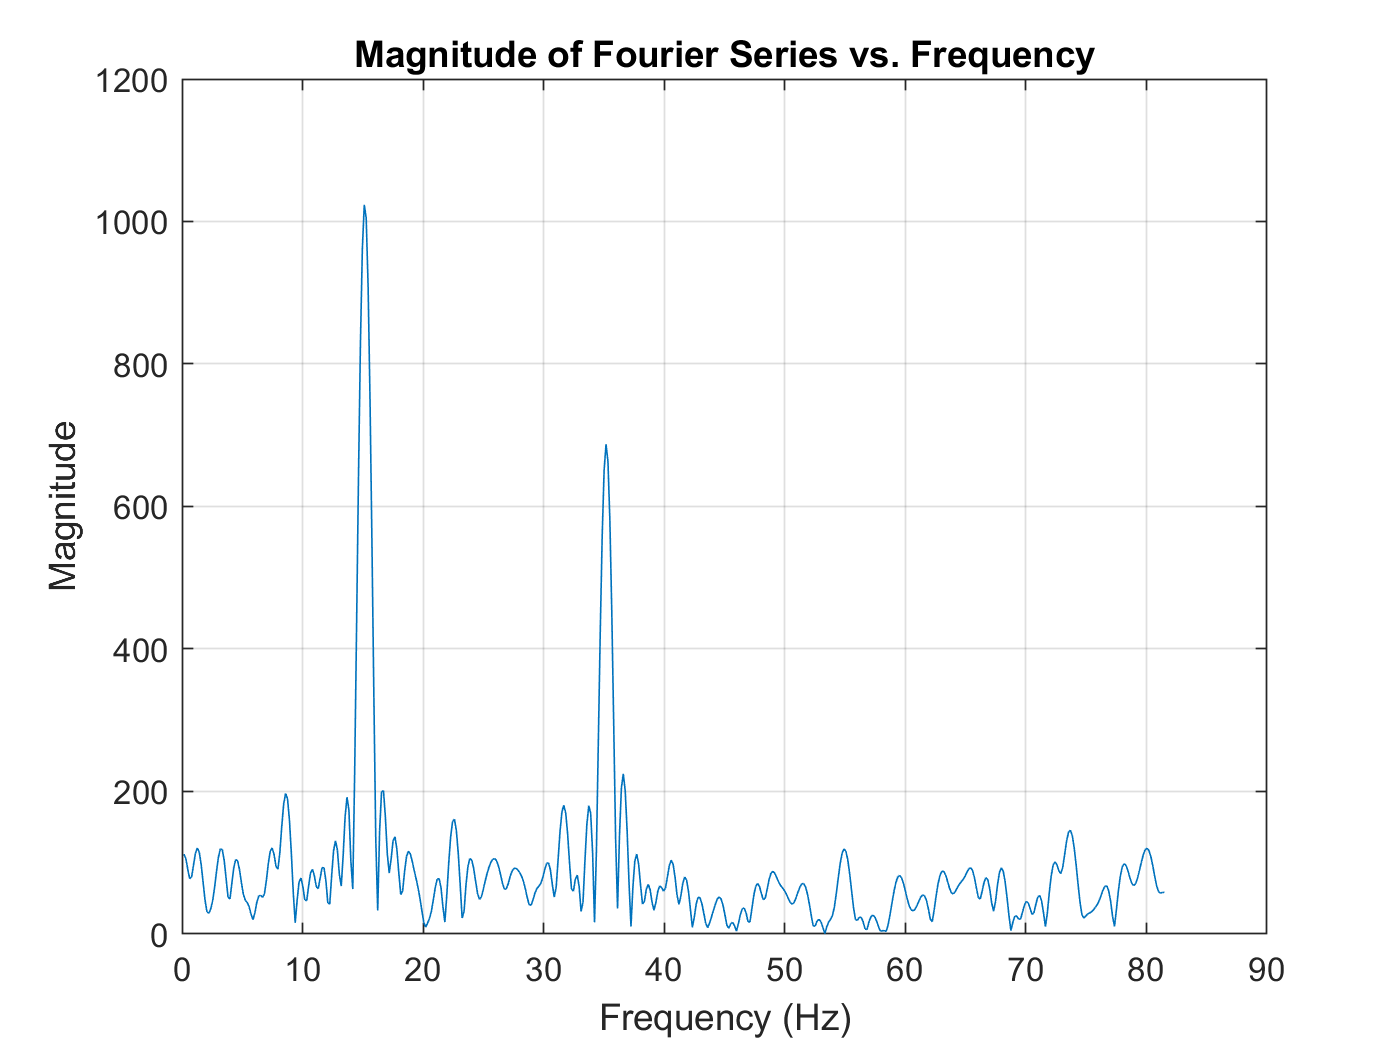

        
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Fourier Series %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
% --Calculate Fourier Series
    for n = 0:(N/2) - 1
        
        % --Create cosine and sine vectors
            Cosine_n = cos(n*w0*t)';
            Sine_n = sin(n*w0*t)';
            
        % --Summation of data
            An = mean(signal * Cosine_n);
            Bn = mean(signal * Sine_n);
        
        % --Calculate magnitude
            Cn = sqrt(An.^2 + Bn.^2);
            phi = atan(Bn / An);
            
        % --Save Values
            magnitude = [magnitude Cn];
            phase = [phase phi];
            
    end
    
% --reformat frequency
    freq = w0 ./ (2*pi);
    freq = freq(1:(N/2));
    phase = phase * pi/2;
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Plot Data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% --Plot Magnitude vs. Frequency
    figure(3)
    plot(freq,magnitude);
        grid on
        hold on
        xline(0,'--')
        xlabel('Frequency (Hz)')
        ylabel('Magnitude')
        title('Magnitude of Fourier Series vs. Frequency')

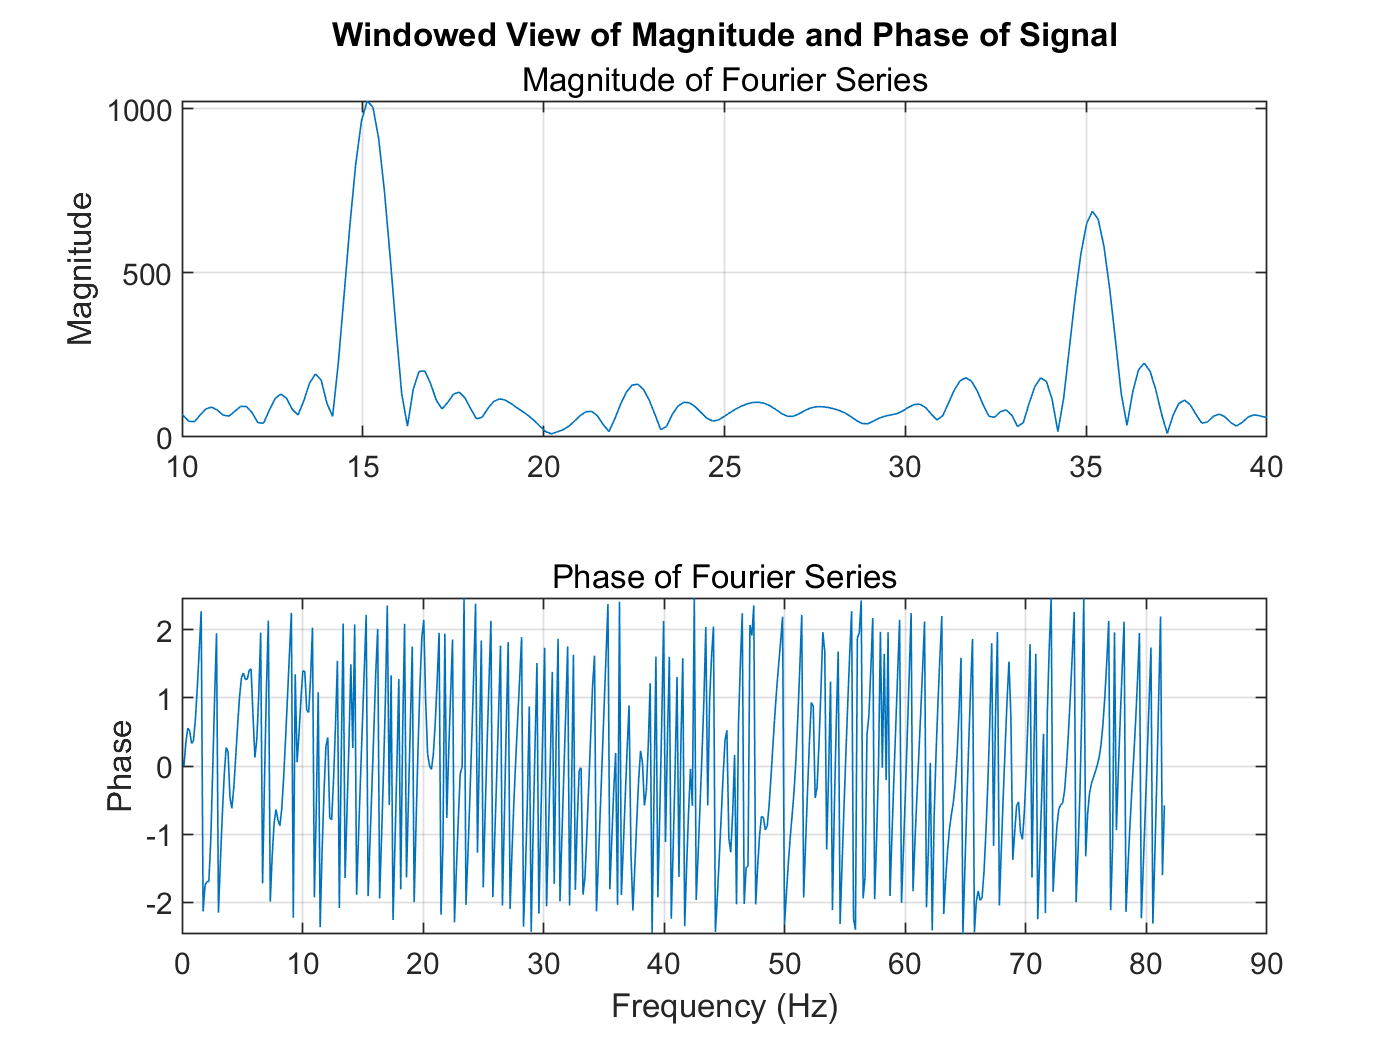

        
     
% --Plot Magnitude and Phase on subplot
    figure(2)
    subplot(2,1,1)
    plot(freq,magnitude, '-')
        xlim([10 40])
        subtitle('Magnitude of Fourier Series')
        title('Windowed View of Magnitude and Phase of Signal')
        ylabel('Magnitude')
        grid on
    
    subplot(2,1,2)
        plot(freq,phase,'-')
        subtitle('Phase of Fourier Series')
        ylabel('Phase')
        xlabel('Frequency (Hz)')
        grid on